# Script 3: Clean NYISO Data

This script focuses on getting the raw data aggregated in Script2 into a clean, useable form.

% clean up
clear
clc

## Examine uncleaned NYISO data

Load in existing data from Script2 and take a look. We can see two problems we will need to resolve:

- We can see in the table output that the data is not regularly sampled.

- If we zoom and pan in the plot, we can see there is both noise and large spikes.

% load mat file saved in Script2
load nyiso_original
% print out first 8 rows
nyisoUnstack(1:8,:)

ans = 8×12 table
           Date            CAPITL    CENTRL    DUNWOD    GENESE    HUDVL    LONGIL    MHKVL    MILLWD    N_Y_C_    NORTH     WEST 
    ___________________    ______    ______    ______    ______    _____    ______    _____    ______    ______    _____    ______

    05/01/2007 00:00:00    981.9     1571.5    557.7     896.6     961.9    1855.9    648.7    226.4     4854.4    691.9    1432.6
    05/01/2007 00:05:00    991.8     1568.9    501.9     904.7     934.3    1883.8    639.3      219     4802.3      701    1426.8
    05/01/2007 00:10:00    950.1     1560.1    502.1     883.5     920.1      1842      649    250.6     4740.3    698.1    1438.4
    05/01/2007 00:13:26    968.9     1560.9    516.9     886.6     927.1    1826.4    657.1    206.1     4697.9    693.4    1437.4
    05/01/2007 00:16:00    968.5     1555.9    489.8     901.5     906.8    1826.6    649.7    217.5     4701.9    686.1    1418.5
    05/01/2007 00:20:26    949.2     1564.7    520.8     885.9   

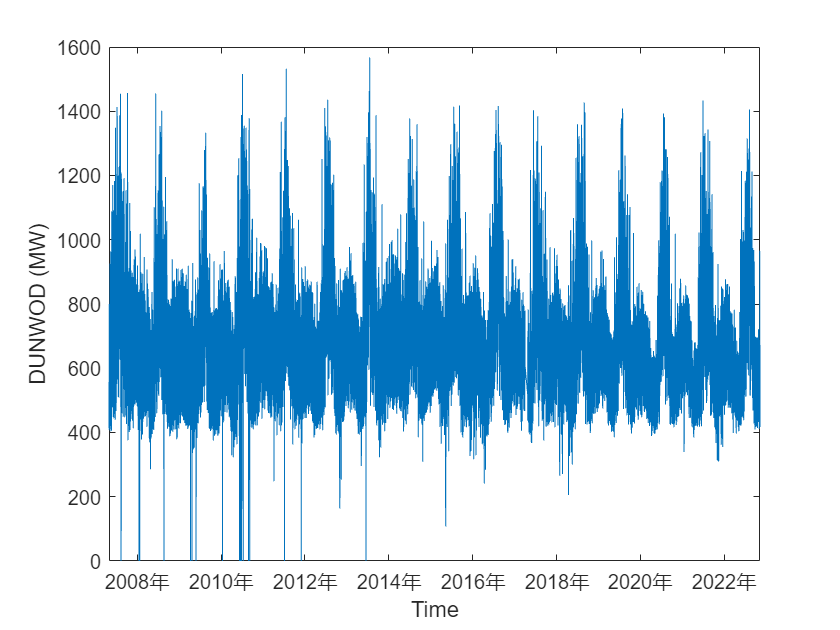

% plot one of the regions over time
region = 'DUNWOD';
plot(nyisoUnstack.Date,nyisoUnstack.(region))
xlabel('Time')
ylabel([region ' (MW)'])

## Regularize the time stamp using `timetable` and `retime`

Out data isn't quite regularly sampled. For convenience, let's get it onto a 5 minute interval. We can do this easily using `timetable`, which is a data type very similar to `table` except that each row much be matched with a time stamp. The `timetable` has a number of functions that work with it to resolve time series related issues. In this case we will use `retime` to get the data onto a 5 minute interval.

% convert the table into a timetable
nyisoRetimed = table2timetable(nyisoUnstack);
% retime the timetable onto a 5 minute interval using a linear interpolant to fill in the values
nyisoRetimed = retime(nyisoRetimed,nyisoRetimed.Date(1):minutes(5):nyisoRetimed.Date(end),'linear');
% print the first 8 rows
nyisoRetimed(1:8,:)

ans = 8×11 timetable
           Date            CAPITL    CENTRL    DUNWOD    GENESE    HUDVL     LONGIL    MHKVL     MILLWD    N_Y_C_    NORTH      WEST 
    ___________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    05/01/2007 00:00:00     981.9    1571.5     557.7     896.6     961.9    1855.9     648.7     226.4    4854.4     691.9    1432.6
    05/01/2007 00:05:00     991.8    1568.9     501.9     904.7     934.3    1883.8     639.3       219    4802.3       701    1426.8
    05/01/2007 00:10:00     950.1    1560.1     502.1     883.5     920.1      1842       649     250.6    4740.3     698.1    1438.4
    05/01/2007 00:15:00    968.66    1557.8    500.36    895.69    914.71    1826.5    652.58    213.06    4700.3    688.94    1425.9
    05/01/2007 00:20:00    951.09    1563.8    517.77    887.42    904.72    1788.7    622.27    245.29    4681.8    700.18    1428.4
    05/01/2007 00:25:00    940.44    154

## Identify spikes in signal

There are a number of places where we get large, multipoint spikes in the signal. We need some way to identify these automatically. There are many possibilities, including:

- Simple thresholding based on signal value or rate of change

- Construct distributions of the values or slopes to recognize outliers in the distribution

- Smoothing data with a spline from Curve Fitting Toolbox

- `findpeaks`, the `hampel` filter, and other filters from Signal Processing Toolbox

- Training a machine learning model to recognize outliers

Here we use a local function `findSpikes` that uses a distribution based approach to the slopes to identify multipoint outliers. The plot below shows a zoomed in portion of the signal, with some of the spikes identified.

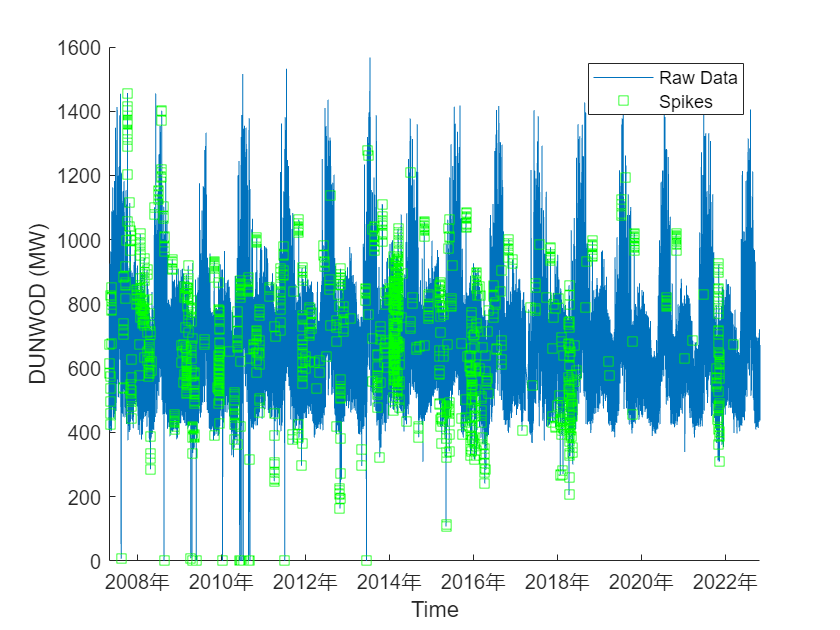

% apply local function to identify spike locations
idxSpike = findSpikes(nyisoRetimed.DUNWOD,14,5,100);
% plot a portion of the signal to visualize spikes
figure
hold on
plot(nyisoRetimed.Date,nyisoRetimed.DUNWOD)
plot(nyisoRetimed.Date(idxSpike),nyisoRetimed.DUNWOD(idxSpike),'gs')
hold off
xlim([datetime('2007-05-01'),datetime('2022-11-01')])
xlabel('Time')
ylabel('DUNWOD (MW)')
legend('Raw Data','Spikes')

## Remove spikes from signal

What caused these spikes in the signal? From the information we have, we really can't say. It's possible they represent bad data points, due to problems such as instrumentation error or data corruption. Or they could be accurately capturing something that is happening in the electricity grid. If so, then the spikes probably warrant further study.

We may wish to study the spikes further at some point, but for now let's remove them so we can focus on the normal behavior. Here we'll remove them using a local function found at the end of this script. The spike values will be replaced by a `NaN`.

nyisoRemove = energyCleanup(nyisoRetimed);

## Missing data

Now that we have removed these spikes from our signal and replaced them with `NaN`'s, let's take a look at the how much missing data we have and where it occurs.

The plot below shows the sparsity of the missing data. Each point represents a `NaN` in our table after removing the spikes. We can see that overall we are missing very little data, less than 0.1% overall, and zooming in on the plot will show that the missing data occurs in small groups.

timetable2table(nyisoRemove)

ans = 1633034×12 table
           Date            CAPITL    CENTRL    DUNWOD    GENESE    HUDVL     LONGIL    MHKVL     MILLWD    N_Y_C_    NORTH      WEST 
    ___________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    05/01/2007 00:00:00     981.9    1571.5     557.7     896.6     961.9    1855.9     648.7     226.4    4854.4     691.9    1432.6
    05/01/2007 00:05:00     991.8    1568.9     501.9     904.7     934.3    1883.8     639.3       219    4802.3       701    1426.8
    05/01/2007 00:10:00     950.1    1560.1     502.1     883.5     920.1      1842       649     250.6    4740.3     698.1    1438.4
    05/01/2007 00:15:00    968.66    1557.8    500.36    895.69    914.71    1826.5    652.58    213.06    4700.3    688.94    1425.9
    05/01/2007 00:20:00    951.09    1563.8    517.77    887.42    904.72    1788.7    622.27    245.29    4681.8    700.18    1428.4
    05/01/2007 00:25:00    940.44    1

% dataSparsityPlot(timetable2table(nyisoRemove))

## Fill in missing values

There are three different ways we might handle missing values:

- Delete any row that contains a missing value

- Fill in the missing value with our best guess

- Leave it there and let MATLAB try to automatically handle it

Which approach is best is highly dependent on the particular problem and goals of the analysis. In this case since the gaps in the missing data are small we can easily fill them in with an interpolant. We will use the `fillmissing` function to fill in the missing values for each column using a spline.

% fill in the missing values, ignoring any missing values at the ends
nyisoFilled = fillmissing(nyisoRemove,'spline','EndValues','none');

## Clean up signal noise

Now that we have retimed the signal and removed the spikes, we still have to deal with the noise in the signal. There are many ways to deal with this. In this case, we will smooth the data using a simple trailing moving average.

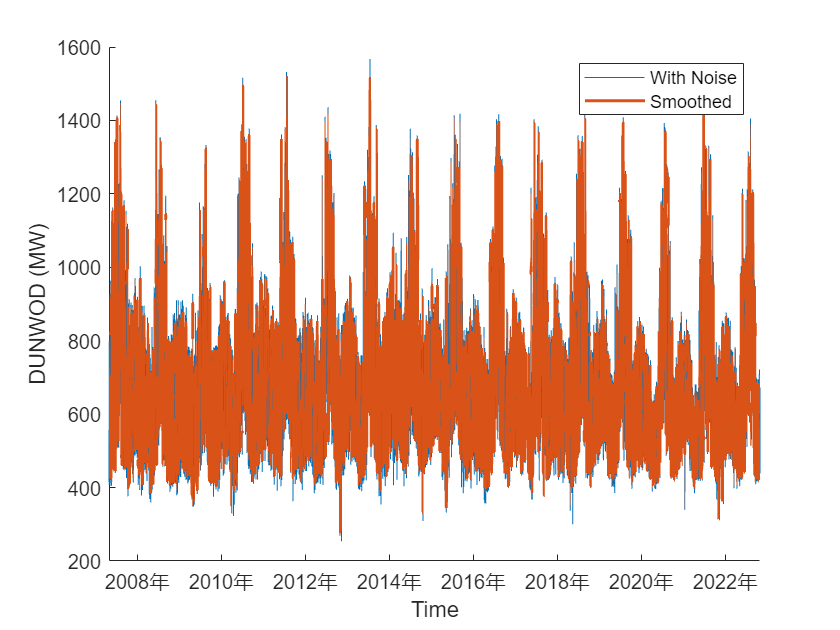

% create trailing moving average with a 1 hour window
nyisoSmooth = nyisoFilled;
nyisoSmooth{:,1:end} = movmean(nyisoFilled{:,1:end},[11,0]);
% plot a comparison of original vs smoothed
figure
hold on
plot(nyisoFilled.Date,nyisoFilled.DUNWOD)
plot(nyisoSmooth.Date,nyisoSmooth.DUNWOD,'LineWidth',1.5)
hold off
xlim([datetime('2007-05-01','TimeZone','America/New_York'),datetime('2022-11-01','TimeZone','America/New_York')])
legend('With Noise','Smoothed')
xlabel('Time')
ylabel('DUNWOD (MW)')

## Save the results for later use

nyiso = nyisoSmooth;
save nyiso_cleaned nyiso
writetimetable(nyiso,'nyiso.csv')

## Local Functions

Starting in R2016b, you can use local functions in live scripts. They work the same as subfunction inside a function file. These functions are only visible to commands run from the script, and they maintain their own workspace. They can only be defined in the last code section of the script.

function idx = findSpikes(y,np,sd,lt,ut)
% idx = findSpikes(y,np,sd,lt,ut)
%
% findSpikes uses slope outliers to detect spikes in a signal. The slopes
% between consecutive points are flagged as outliers if they are +/- 'sd'
% standard deviations from the mean slope. If an outlier slope in one
% direction is followed within 'np' points of an outlier slope in the
% opposite direction, all points between those two slopes are flagged.
%
% Inputs:
%   y       input signal containing spikes to be identified
%   np      maximum number of points in spike (default: 1)
%   sd      number of standard deviations from mean slope to use as
%           threshold for slope outlier (default: 2.5)
%   lt      lower threshold, all points below this will be flagged (default: -inf)
%   ut      upper threshold, all points above this will be flagged (default: inf)
%
% Outputs:
%   idx     logical index of points that were flagged as spikes
%
% Copyright 2014-2016 The MathWorks, Inc.

% default value for np is 1
if nargin < 2 || isempty(np)
    np = 1;
end
% default value for sd is 2.5
if nargin < 3 || isempty(sd)
    sd = 2.5;
end
% default value for lt is -inf
if nargin < 4 || isempty(lt)
    lt = -inf;
end
% default value for ut is inf
if nargin < 5 || isempty(ut)
    ut = inf;
end

% flag anomalies below lower threshold or above upper threshold
idxout = y < lt | y > ut;

% calculate the slope
dy = diff(y);

% create the threshold
st = std(dy); % standard deviation of the slope
mn = mean(dy); % mean of the slope

% where do large changes happen
idxup = dy > mn+sd*st; % large positive change
idxdown = dy < mn-sd*st;  % large negative change
idxuploc = find(idxup); % locations where large positive change occurred
idxdownloc = find(idxdown); % locations where large negative change occurred
idxup_anom = false(length(idxup),1); % preallocate array for storing location of positive anomalies
idxdown_anom = false(length(idxdown),1); % preallocate array for storing location of negative anomalies

% identify anomalies in the positive direction, e.g. large positive
% slope followed by large negative slope within a certain number of
% measurements
for ii = 1:length(idxuploc) % for each location where large positive slope exists...
    % find places where the location of large negative slope comes after a
    % positive anomaly within a certain threshold of points
    idxmatch = idxdownloc-idxuploc(ii) <= np & idxdownloc-idxuploc(ii) > 0;
    % if there's any large negative slopes that match the criteria
    if any(idxmatch)
        % find where they occur, and from the location where the positive
        % slope is recorded to the location before the negative slope is
        % recorded set the value to true, signaling an anomaly
        m = find(idxmatch);
        % if there are multiple large down slopes in range, pick the last
        % one to capture the full anomaly
        idxup_anom(idxuploc(ii):idxdownloc(m(end))-1)=true;
    end
end
% identify anomalies in the negative direction
for jj = 1:length(idxdownloc)
    idxmatch = idxuploc-idxdownloc(jj) <= np & idxuploc-idxdownloc(jj) > 0;
    if any(idxmatch)
        m = find(idxmatch);
        idxdown_anom(idxdownloc(jj):idxuploc(m(end))-1)=true;
    end
end
% combine the different anomalies
idx = idxup_anom | idxdown_anom;
% pad idx because we lost a point when subtracting for the slope
idx = [false;idx] | idxout; 
end

function tbl = energyCleanup(tbl)
% helper function used to find and remove spikes

% loop through each column of the table
for ii = 1:width(tbl)
    ul = [];
    % specifying the upper limit isn't necessary for most regions
    % however it can help with the NORTH region as some large spikes
    % can be difficult to identify without it
    if strcmp(tbl.Properties.VariableNames{ii},'NORTH')
        ul = 1000;
    end
    % find the spikes to remove
    idxRemove = findSpikes(tbl.(ii),14,5,5,ul);
    % remove them
    tbl.(ii)(idxRemove) = NaN;
end
% add the time zone
tbl.Date.TimeZone = 'America/New_York';
% make sure it is still on the five minute interval
tbl = retime(tbl,tbl.Date(1):minutes(5):tbl.Date(end));
end

*Copyright 2014-2018 The MathWorks, Inc.*